## FRKSKIA001 and CLRCAM007 ES3 

### Prac 2

#### Prac 2.2: Parallel Processing in MATLAB 

% Create parallel pools
delete(gcp('nocreate'));

Parallel pool using the 'Processes' profile is shutting down.


p = parpool('Processes', 4);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


2.2.(a) This short task involves implementing the easy Bubble sort routine, just using looping, don’t attempt any parallelization. First implement Bubble sort, in the regular fashion, by using a nested for loop. A good explanation is given at: https://medium.com/codex/bubble-sorthow-it-works-psuedocode-and-c-python-implementationc45306d44827. Apply sorting to a 100x100 matrix of random numbers, you just use rand for generating random floats in the range (0,1). Sort the columns from minimum value to maximum value, like the MATLAB sort command does. i.ew. you will need another for loop for go through sorting each column of the matrix one column at a time. (NOTE: obviously not using the built in sort function). [10 marks]

Creating a bubble sort function look at BubbleSort

Testing the Bubble sort function

X=rand(100,100)

X =     0.3150    0.6114    0.7599    0.7739    0.4048    0.3990    0.9050    0.8836    0.9898    0.2649    0.9783    0.4530    0.3182    0.7334    0.1560    0.3848    0.3129    0.4162    0.2251    0.2129    0.6440    0.7282    0.5158    0.7234    0.9099    0.4965    0.7129    0.0913    0.2828    0.4871    0.8189    0.4445    0.4176    0.9720    0.9679    0.6681    0.0713    0.2126    0.0842    0.4725    0.1326    0.1410    0.1964    0.4691    0.9427    0.9241    0.9031    0.8626    0.6978    0.5691
    0.7619    0.0816    0.4990    0.0458    0.4277    0.1943    0.1546    0.0184    0.7028    0.0041    0.7384    0.3855    0.0837    0.0619    0.7598    0.6326    0.2733    0.7141    0.2631    0.1484    0.3147    0.6320    0.0053    0.3423    0.1247    0.1755    0.3616    0.3279    0.6178    0.8084    0.1551    0.1556    0.5259    0.4284    0.8875    0.1659    0.4787    0.2528    0.2525    0.3887    0.8287    0.0157    0.3737    0.8942    0.2685    0.6346    0.9691    0.5687    0.7988    0


for i = 1:100 
  X(:,i) = BubbleSort(X(:,i));
end 

2.2.(b) How does the built-in sort function compare in run time to your sequential sort implementation? Test, at least, for square matrixes of sizes 100, 200, 500, 1000, 10000. [5 marks]

% Initialize the cell array
testsizes = [100; 200; 500; 1000; 1200];
timetaken = cell(1+length(testsizes),4);
timetaken(1,:) = {"size", "bubble sort time", "inbuilt sort time", "speed up"};
timetaken(2:end,1) = num2cell(testsizes); % should use [100; 200; 500; 1000; 10000] but takes too long so using 1100 for know 

% Loop over each row in timetaken
for i = 2:size(timetaken,1)
    % Call the timetest function with the value in the first column of the i-th row
    [timeBubble, timeInbuilt] = timetest(timetaken{i,1});
    timetaken{i,2} = timeBubble;
    timetaken{i,3} = timeInbuilt;
    % Calculate speed up
    timetaken{i,4} = timeBubble/timeInbuilt;
end

    "Time tacken by the bubble sort function was 0.0054761 s. Time tacken by the inbuilt sort function was: 0.0006824 s."

    "Time tacken by the bubble sort function was 0.035349 s. Time tacken by the inbuilt sort function was: 0.003444 s."

    "Time tacken by the bubble sort function was 0.46863 s. Time tacken by the inbuilt sort function was: 0.0185 s."

    "Time tacken by the bubble sort function was 3.0949 s. Time tacken by the inbuilt sort function was: 0.083055 s."

    "Time tacken by the bubble sort function was 5.1646 s. Time tacken by the inbuilt sort function was: 0.10148 s."




% Display the results
disp(timetaken)

    {["size"]}    {["bubble sort time"]}    {["inbuilt sort time"]}    {["speed up"]}
    {[   100]}    {[            0.0055]}    {[         6.8240e-04]}    {[    8.0248]}
    {[   200]}    {[            0.0353]}    {[             0.0034]}    {[   10.2640]}
    {[   500]}    {[            0.4686]}    {[             0.0185]}    {[   25.3311]}
    {[  1000]}    {[            3.0949]}    {[             0.0831]}    {[   37.2629]}
    {[  1200]}    {[            5.1646]}    {[             0.1015]}    {[   50.8933]}



plotting the grafs

% Create a new figure
figure

% Create the first subplot
subplot(2,1,1)
% Create a bar graph of the time taken by the Bubble Sort function and MATLAB's built-in sort function
bar(cell2mat(timetaken(2:end ,2:3)));
% Add labels and title
xlabel('Arry Size')
ylabel('Time Taken in s (logarythmic)')
set(gca, 'YScale', 'log')
title('Time Taken by Bubble Sort and Inbuilt Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken(2:end,1))

% Add a legend
legend('Bubble Sort Time', 'Inbuilt Sort Time')


% Create the second subplot
subplot(2,1,2)
% Create a bar graph of the speed up
bar(cell2mat(timetaken(2:end ,4)));
% Add labels and title
xlabel('Array Size')
ylabel('Speed Up')
title('Speed Up of Inbuilt Sort Over Bubble Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken(2:end,1))

2.2.(c) Now for a bit of explicit parallelism (the MATLAB sort function tends to use implicit parallelism, i.e. you aren’t so aware of it being a parallel function). Use a parfor or spmd block to parallelize sorting of the columns of X. Test at least matrices of size 100, 5000 [15 marks]

% Initialize the cell array
testsizes = [100, 5000];
timetaken_par = cell(1+length(testsizes),4);
timetaken_par(1,:) = {"size", "bubble sort time", "inbuilt sort time", "speed up"};
timetaken_par(2:end,1) = num2cell(testsizes); % should use [100; 200; 500; 1000; 10000] but takes too long so using 1100 for know 

% Loop over each row in timetaken_par
for i = 2:size(timetaken_par,1)
    % Call the timetest function with the value in the first column of the i-th row
    timeBubble = timebubble_parallelism(timetaken_par{i,1});
    timeInbuilt = timesort_parallelism(timetaken_par{i,1}); 
    timetaken_par{i,2} = timeBubble;
    timetaken_par{i,3} = timeInbuilt;
    % Calculate speed up
    timetaken_par{i,4} = timeBubble/timeInbuilt;
end

Worker 1: 
  
  myStart =
  
       1
  
  
  myEnd =
  
      25
  
Worker 2: 
  
  myStart =
  
      26
  
  
  myEnd =
  
      50
  
Worker 3: 
  
  myStart =
  
      51
  
  
  myEnd =
  
      75
  
Worker 4: 
  
  myStart =
  
      76
  
  
  myEnd =
  
     100
  
    "Time tacken by the parallelism bubble sort function was 0.7642"



    "Time tacken by the sort function was 0.000999"



Worker 1: 
  
  myStart =
  
       1
  
  
  myEnd =
  
          1250
  
Worker 3: 
  
  myStart =
  
          2501
  
  
  myEnd =
  
          3750
  
Worker 2: 
  
  myStart =
  
          1251
  
  
  myEnd =
  
          2500
  
Worker 4: 
  
  myStart =
  
          3751
  
  
  myEnd =
  
          5000
  
    "Time tacken by the parallelism bubble sort function was 111.7174"



    "Time tacken by the sort function was 1.0715"




% Display the results
disp(timetaken_par)

    {["size"]}    {["bubble sort time"]}    {["inbuilt sort time"]}    {["speed up"]}
    {[   100]}    {[            0.7642]}    {[         9.9900e-04]}    {[  764.9609]}
    {[  5000]}    {[          111.7174]}    {[             1.0715]}    {[  104.2645]}



Ploting bar graphs for this qustion 

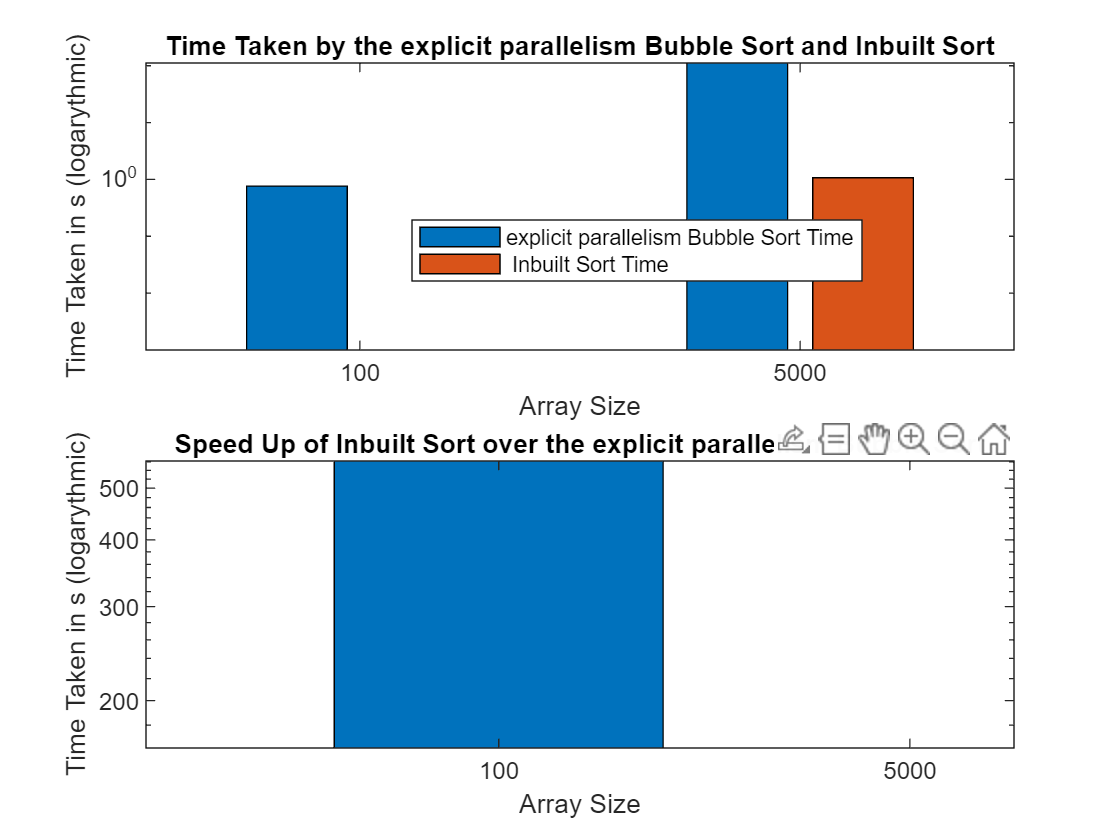


% Create a new figure
figure

% Create the first subplot
subplot(2,1,1)
% Create a bar graph of the time taken by the Bubble Sort function and MATLAB's built-in sort function
bar(cell2mat(timetaken_par(2:end ,2:3)));
% Add labels and title
xlabel('Array Size')
ylabel('Time Taken in s (logarythmic)')
set(gca, 'YScale', 'log')
title('Time Taken by the explicit parallelism Bubble Sort and Inbuilt Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken_par(2:end,1))

% Add a legend
legend('explicit parallelism Bubble Sort Time', ' Inbuilt Sort Time')




% Create the second subplot
subplot(2,1,2)
% Create a bar graph of the speed up
bar(cell2mat(timetaken_par(2:end ,4)));
% Add labels and title
xlabel('Array Size')
ylabel('Time Taken in s (logarythmic)')
set(gca, 'YScale', 'log')
title('Speed Up of Inbuilt Sort over the explicit parallelism Bubble Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken_par(2:end,1))

% destroy parallel tools
p.delete;

Parallel pool using the 'Processes' profile is shutting down.
